# Solution to *Corporate Bonds: Import and Organize* exercise

## 1. Import data

Import the data in `BondData.xls` into a table.

data = readtable('BondData.xls');

This file contains simulated data that reflects characteristics of corporate bonds including the type of bond, name, price, coupon rate, maturity date, yield to maturity (YTM), current yield, rating, and whether it is callable or not.

## 2. Convert to categorical

Convert the `Type` and `Rating` variables to categorical data types.

data.Type = categorical(data.Type);
rnames = {'AAA','AA','A','BBB','BB','B','CCC','CC','D'};
data.Rating = categorical(data.Rating,rnames);

## 3. Extract corporate bonds into separate table

corpData = data(data.Type == 'Corp',:);

## 4. Keep those with YTM greater than zero and less than 30

Among the corporate bonds, keep only those whose YTM is greater than zero and less than 30.

idx = corpData.YTM >= 0 & corpData.YTM < 30;
corpData = corpData(idx,:);

## 5. Grouped scatter plot

Create a grouped scatter plot of the corporate bonds with `Coupon` on the *x*-axis and YTM on the *y*-axis, grouped by `Rating`.

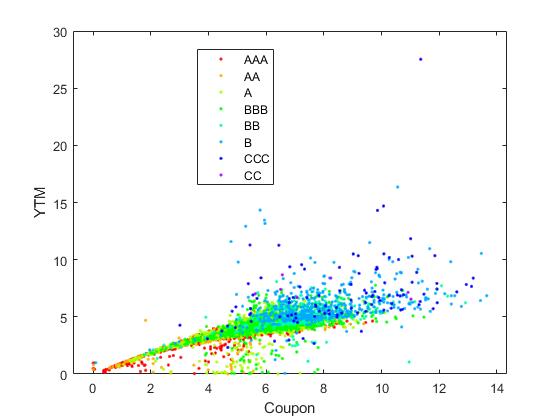

gscatter(corpData.Coupon,corpData.YTM,corpData.Rating)
xlabel('Coupon')
ylabel('YTM')